# Generate Data

clear;clc;
addpath("gendata_helper");
addpath("Tools");


We assume that the communication between agents are shown in graph.

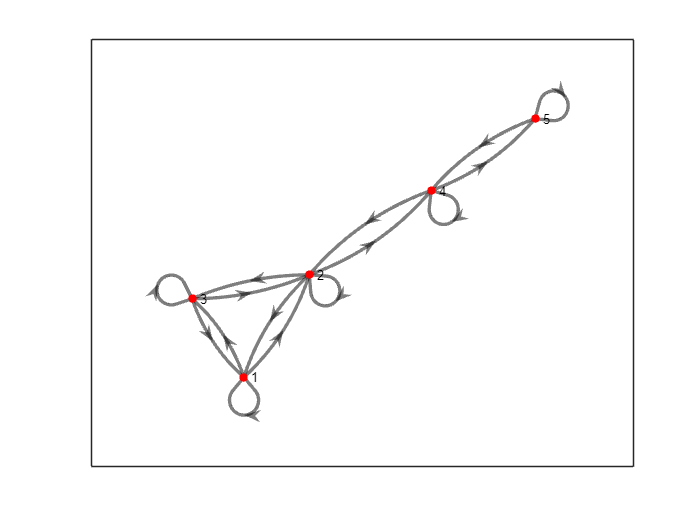

A=[1,1,1,0,0;
    1,1,1,1,0;
    1,1,1,0,0;
    0,1,0,1,1;
    0,0,0,1,1];
G=digraph(A);
plot(G,'LineWidth',2,'EdgeColor','k','NodeColor','r','Layout','auto','ArrowSize',10,'layout','auto')

## Generate Trajectory for Each Robot

% 1. Parameters
T_WORKING=8; %
dti=0.01; %The sample interval of the IMU/estimator(s), i.e. IMU's frequency is 100Hz
scale=1;
dtc=0.03; %The sample interval of camera.
dt_object=0.05;
%
sigma_bg=0.01; 
sigma_ba=0.01; 
sigma_a=0.02; %%0.01
sigma_g=0.02;

b_g_real=[0.02,0.01,0.02];%bias 
b_a_real=[0.03,0.05,0.03];
g_real=[0;0;-9.81];

% Parameters related with camera
sigma_cam=1;  % pixels
fx=460;
fy=460;
cx=255;
cy=255;
image_w=640;
image_h=640;
p_camera_in_IMU_real = [0.0, 0.0, 0.0]/scale;
R_camera_in_IMU_real = angle2dcm(0,0 , 0);

%2. Effective measurement range (about landmark)
Eff_Range=30;

%3. Trajectory setting
% Assign initial positions for robots and center 
Position0=[-3,60,0; 
            -10,30,0; 
            25, 75,3; 
            60,-60,5;
            120,-150,-2];
Position0=0.5*Position0;
%4. Generate object landmarks and assign bounding box
% Generate many landmarks
NL1=0;
NL2=3;
NL3=5;
NL4=15;
NL5=15;



landm_pos1=[10*randn(NL1,2),10*randn(NL1,1)]+Position0(1,:);
landm_pos2=[25*randn(NL2,2),5*randn(NL2,1)]+Position0(2,:);
landm_pos3=[24*randn(NL3,2),3*randn(NL3,1)]+Position0(3,:);
landm_pos4=[30*randn(NL4,2),3*randn(NL4,1)]+Position0(4,:);
landm_pos5=[25*randn(NL5,2),3*randn(NL5,1)]+(Position0(5,:)+Position0(4,:))/2;
landm_pos=[landm_pos1;landm_pos2;landm_pos3;landm_pos4;landm_pos5];
scatter3(landm_pos(:,1), landm_pos(:,2), landm_pos(:,3),0.1,'filled'); hold on
N_LANDMARKS=NL1+NL2+NL3+NL4+NL5;
rotlist=zeros(N_LANDMARKS,3);
for uu=1:N_LANDMARKS
    T_f=eye(4);
    Rot1=randn(1,1)*3.14;
    Rot2=randn(1,1)*3.14;
    Rot3=randn(1,1)*3.14;

    rotlist(uu,:)=[Rot1, Rot2, Rot3];
    Rot=angle2dcm(Rot1,Rot2,Rot3);
    T_f(1:3,1:3)=Rot;
    T_f(1:3,4) = landm_pos(uu,:)';
    landmarks(uu).T = T_f;
    
end
%Generate Bounding Box
Draw_bounding_box(landmarks); hold on

%%debug only focus on one robot
trigK=[4.5,1,1.5;
       2.0,2.0,3;
       2.5,1,4.5; 
       3.5,1,2.5;
       4.5,3,3.5]; % parameters about trajectory
Robot=[];
for i=1:5
    num=num2str(i);
    [Robot(i).real_path,Robot(i).T_real0] = gen_trajectory(T_WORKING, dti, Position0(i,:),trigK(i,:),num);
    axis equal
    Robot(i).IMU_data = IMU_gendata(Robot(i).real_path,b_g_real,b_a_real,sigma_g, sigma_a, dti);
end





## Generate measurements about the landmark

We assume that the whole system keep a fixed frequency to interchange their information. 

i.e., at the same time ("system update time"), there will be agent-to-feature measurement and agent-to-agent measurement.

The system is dynamic, and only in the effective range then agents can see the feature.

%1. Pose measurements
sigma_if=[0.01,0.001,0.001,0.001,0.001];
sigma_ij=[0.0001,0.0001,0.0001,0.0001,0.0001];
m_data=gen_measurement_SE3(Eff_Range, landmarks, A, sigma_if, sigma_ij, trigK, Position0, T_WORKING, dt_object);

%2. Camera measurements
N_LMCAMERA=200;% The number of camera's landmarks, it should be an integral multiple of 4 
lm_camera=camera_genlandmark(N_LMCAMERA,[60,-60,0],[150,120,50]); %generate camera's landmarks, 5*5=25
CAM_INTRISIC.FOV=pi/3;
CAM_INTRISIC.fx=fx;
CAM_INTRISIC.fy=fy;
CAM_INTRISIC.cx=cx;
CAM_INTRISIC.cy=cy;    
CAM_INTRISIC.image_w=image_w;
CAM_INTRISIC.image_h=image_h;
CAM_INTRISIC.tc=dtc; 
CAM_INTRISIC.sigma_cam=sigma_cam;

% Remark: for simulation simplicity, the parameters of cameras are set to
% be the same. But you can modify to different setting easily.
for i=1:5
    Robot(i).camera_data = camera_gendata(CAM_INTRISIC, lm_camera, (T_WORKING+dtc), p_camera_in_IMU_real, R_camera_in_IMU_real,dtc, Position0(i,:),trigK(i,:)); 
end

landmark number mean:
25.9193
landmark number mean:
56.8456
landmark number mean:
16.0667
landmark number mean:
104.9614
landmark number mean:
168.1333




grid off

### Save New Data

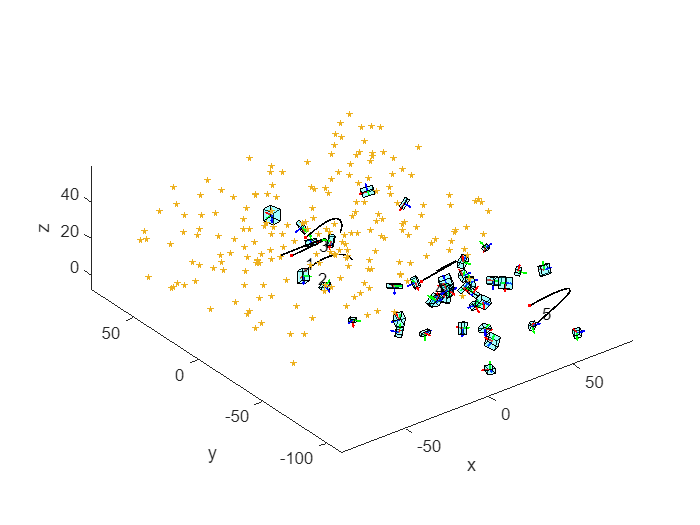

folder='dataset'; 
if exist(folder)==0 
    mkdir(folder); 
end
datasetname='data_sy';
savename=[folder,'/',datasetname,'.mat'];
save(savename);

% 
f=gcf;
name = [datasetname,'.pdf'];
savepath1 = [folder,'/',name];
exportgraphics(f,savepath1)